Well = @(u)integral(@(x)exp(-x)./x,u,10);

np =100;
inv_u=logspace(log10(3e-1), 4, np);
u=inv_u.^-1;

for i=1:np
    W(i)=Well(u(i));
end

Q=200/7.4805;
r=250;
t_min= [0.1 1 1.5 2 2.5 3 4 5 6 8 10 12 14 18 24 30 40 50 60 80 100 120 150 180 210 240];
d_ft= [0.001 0.66 0.87 0.99 1.11 1.21 1.36 1.49 1.59 1.75 1.86 1.97 2.08 2.20 2.36 2.49 2.65 2.78 2.88 3.04 3.16 3.28 3.42 3.51 3.61 3.67];

tm= 0.21;
dhm= 0.568;

T=Q/4/pi/dhm*1;
S=4*T*tm/r^2;
txt=sprintf('T = %5.3f ft^2/m  \nS = %5.4g', T, S);

ud=(t_min/tm).^-1;
npd=length(ud);
for i=1:npd
    Wd(i)=Well(ud(i));
end 
hdc=Q/4/pi/T*Wd;

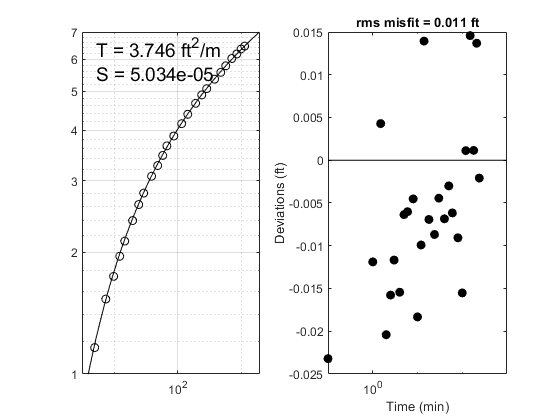

subplot(121)
loglog(t_min/tm, d_ft/dhm, 'ko')
hold on
loglog(inv_u, W, 'k-')
hold off
xlim([3 2000])
ylim([1 7])
text(5, 6, txt, 'FontSize', 14)
grid on

subplot(122)
semilogx(t_min,d_ft-hdc,'ko', 'MarkerFaceColor', 'k')
hold on
semilogx([0.1 1e3], [0 0], 'k-')
xlabel('Time (min)')
ylabel('Deviations (ft)')
msfit=sqrt(sum((d_ft-hdc).^2)/length(d_ft));
txt=sprintf('rms misfit = %5.3f ft', msfit);
title(txt)
hold off

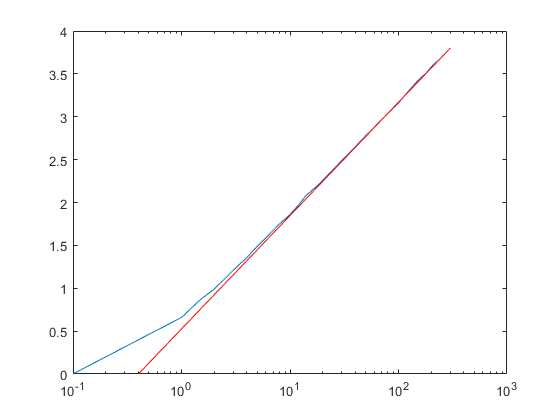

figure;
semilogx(t_min, d_ft)
hold on
line([0.4 300], [0 3.8], 'Color', 'r')
hold off